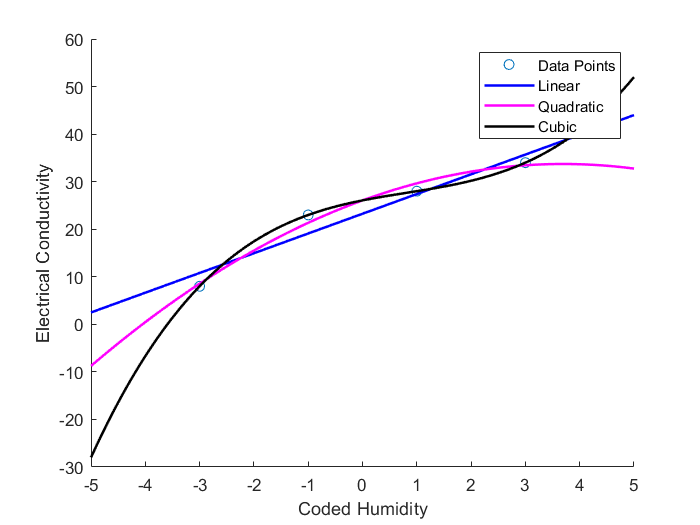

act_x = [-3 -1 1 3];
act_y = [8 23 28 34];
l1 = scatter(act_x,act_y);
hold on


x_vec = [-3 -1 1 3];
A = zeros(4,2);
A(:,1) = 1;
A(:,2) = x_vec;
A_t = transpose(A);
b_vec = [8, 23, 28, 34];
A_star = A_t*A;
b_star = A_t*b_vec';
xls = mldivide(A_star,b_star);

x = linspace(-5,5,100);
linear = xls(1) + xls(2)*x;

l2 = plot(x, linear, "-b", "LineWidth", 1.5);
xlabel ("Coded Humidity")
ylabel ("Electrical Conductivity")
hold on


x_vec = [-3 -1 1 3];
A = zeros(4,3);
A(:,1) = 1;
A(:,2) = x_vec;
A(:,3) = x_vec.^2;
A_t = transpose(A);
b_vec = [8, 23, 28, 34];
A_star = A_t*A;
b_star = A_t*b_vec';
xls = mldivide(A_star,b_star);

x = linspace(-5,5,100);
quad = xls(1) + xls(2)*x + xls(3)*x.^2;
l3 = plot(x,quad,"-m", "LineWidth", 1.5);
hold on


x_vec = [-3 -1 1 3];
A = zeros(4,4);
A(:,1) = 1;
A(:,2) = x_vec;
A(:,3) = x_vec.^2;
A(:,4) = x_vec.^3;
A_t = transpose(A);
b_vec = [8, 23, 28, 34];
A_star = A_t*A;
b_star = A_t*b_vec';
xls = mldivide(A_star,b_star);

x = linspace(-5,5,100);
quad = xls(1) + xls(2)*x + xls(3)*x.^2 + xls(4)*x.^3;
l4 = plot(x,quad, "-k", "LineWidth", 1.5);
hold on
legend show
legend([l1, l2, l3, l4], ["Data Points", "Linear", "Quadratic", "Cubic"])